# Figure 1 (Methods) - Excitation lights and filters

We plot the estimated excitation light levels including the short pass filter in front of the light at 450nm in the rig. This was always present when we made the fluorescence measurements. These files are labeled ('Calib' or 'calib').

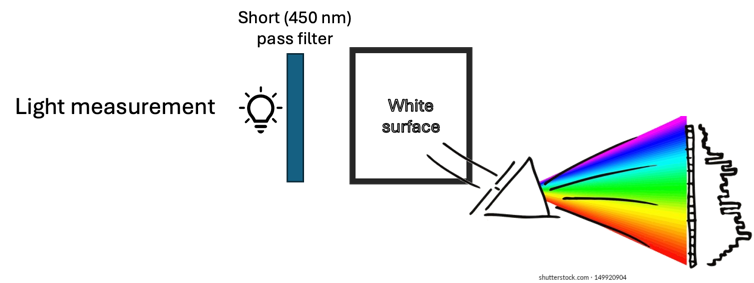

When we made the fluorescence measurements (see oeFigure1_compareSubjects) we placed a 475nm long pass filter in front of the spectroradiometer.  Its purpose is to block the reflected light from the intense short wavelength light sources.  These were at 405, 415, and 450nm.

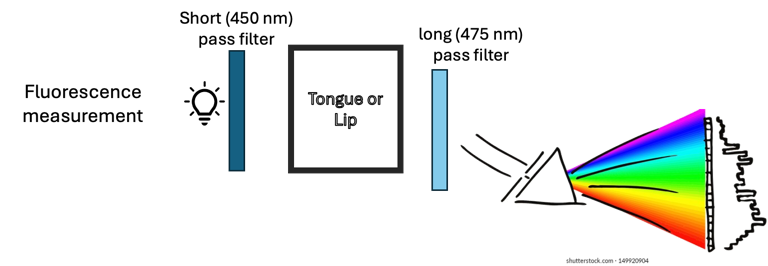

To estimate how much light might have been reflected from the tongue and still pass through the 475nm, we  made measurements (labeled 'noisecheck') replacing the tongue/lip with a white surface.  This surface had no fluorescence, so that any light that made it through would be standard reflectance.  We estimated the maximum reflected light by taking this calibration measurement and multiplying by the standard tongue reflectance.

## Initialize ISET

ieInit;
waves = 380:4:700;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseLightsCreate;

## LED-405

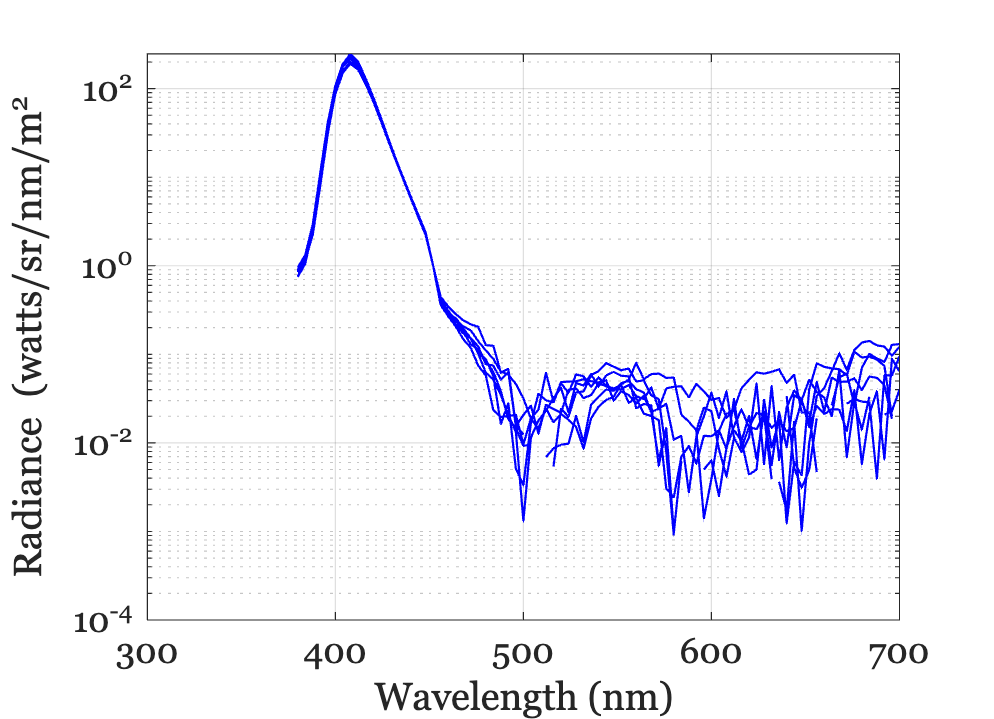

files = ieTableGet(T,'condition','calibrate','ewave',405);
data = oeReadFiles(files,'waves',waves,'normalized wave',452);
ieFigure;
semilogy(waves,data,'b-'); hold on;
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2');

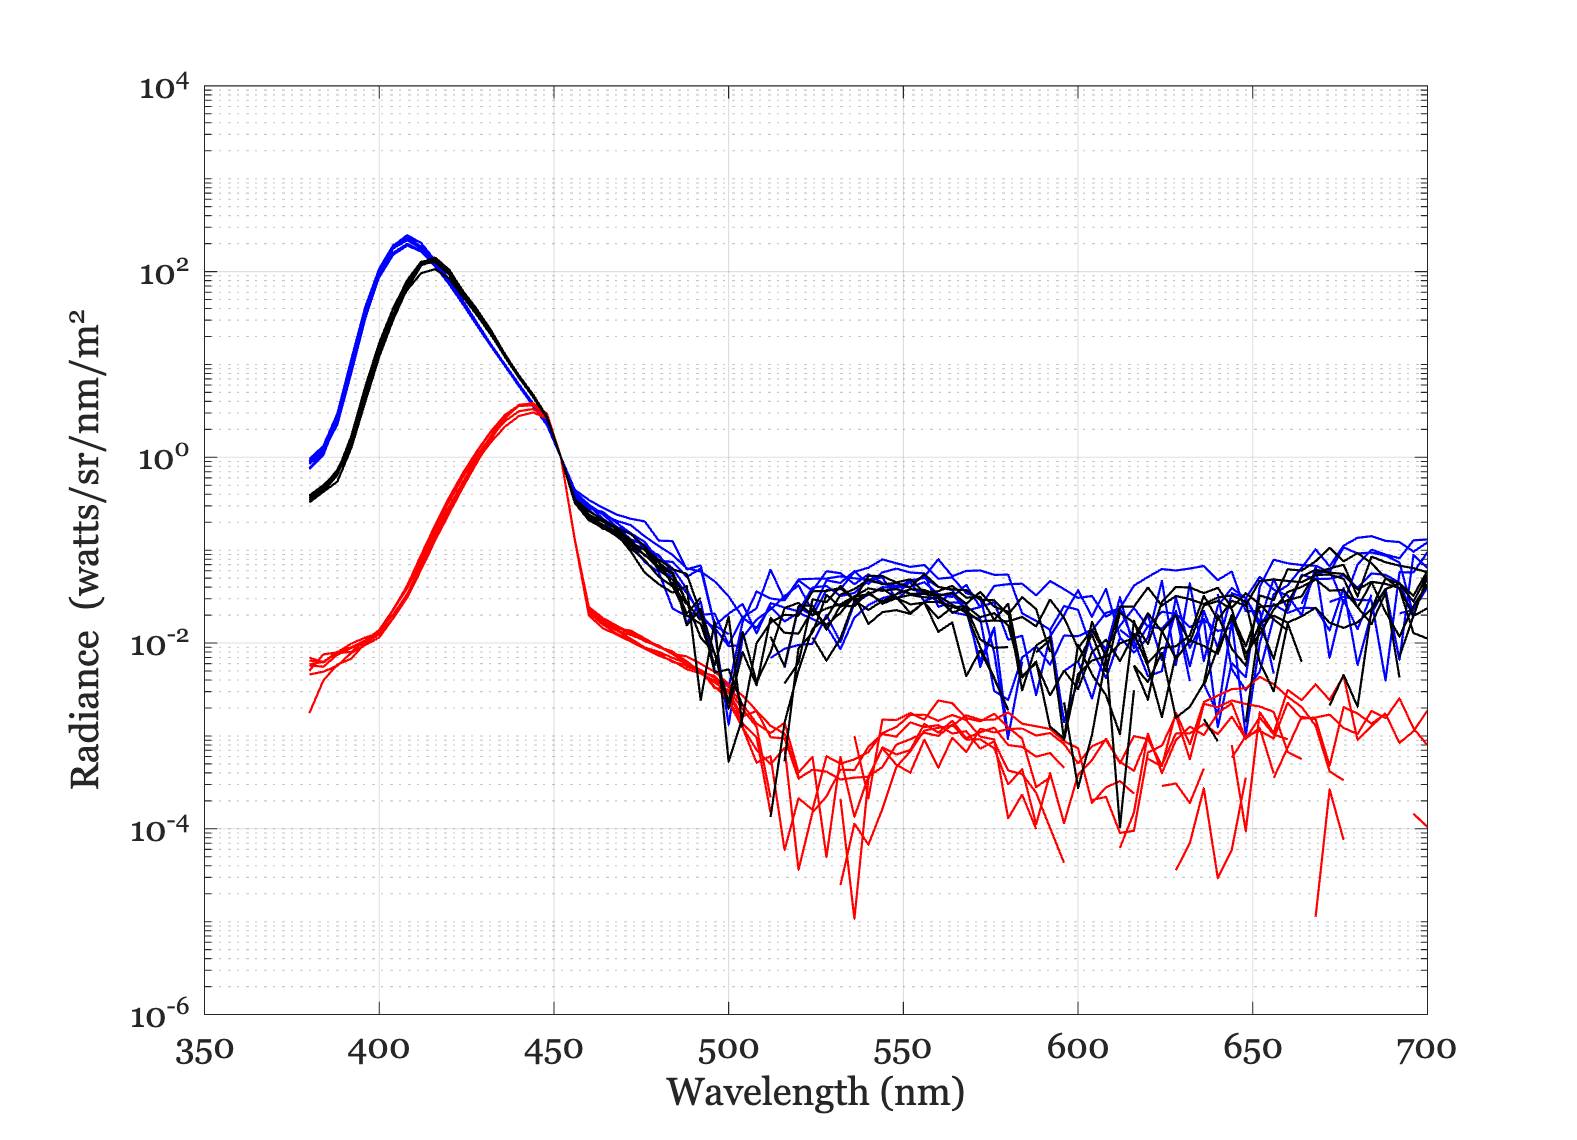

files = ieTableGet(T,'condition','calibrate','ewave',415);
data = oeReadFiles(files,'waves',waves,'normalized wave',452);
semilogy(waves,data,'k-');
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2');

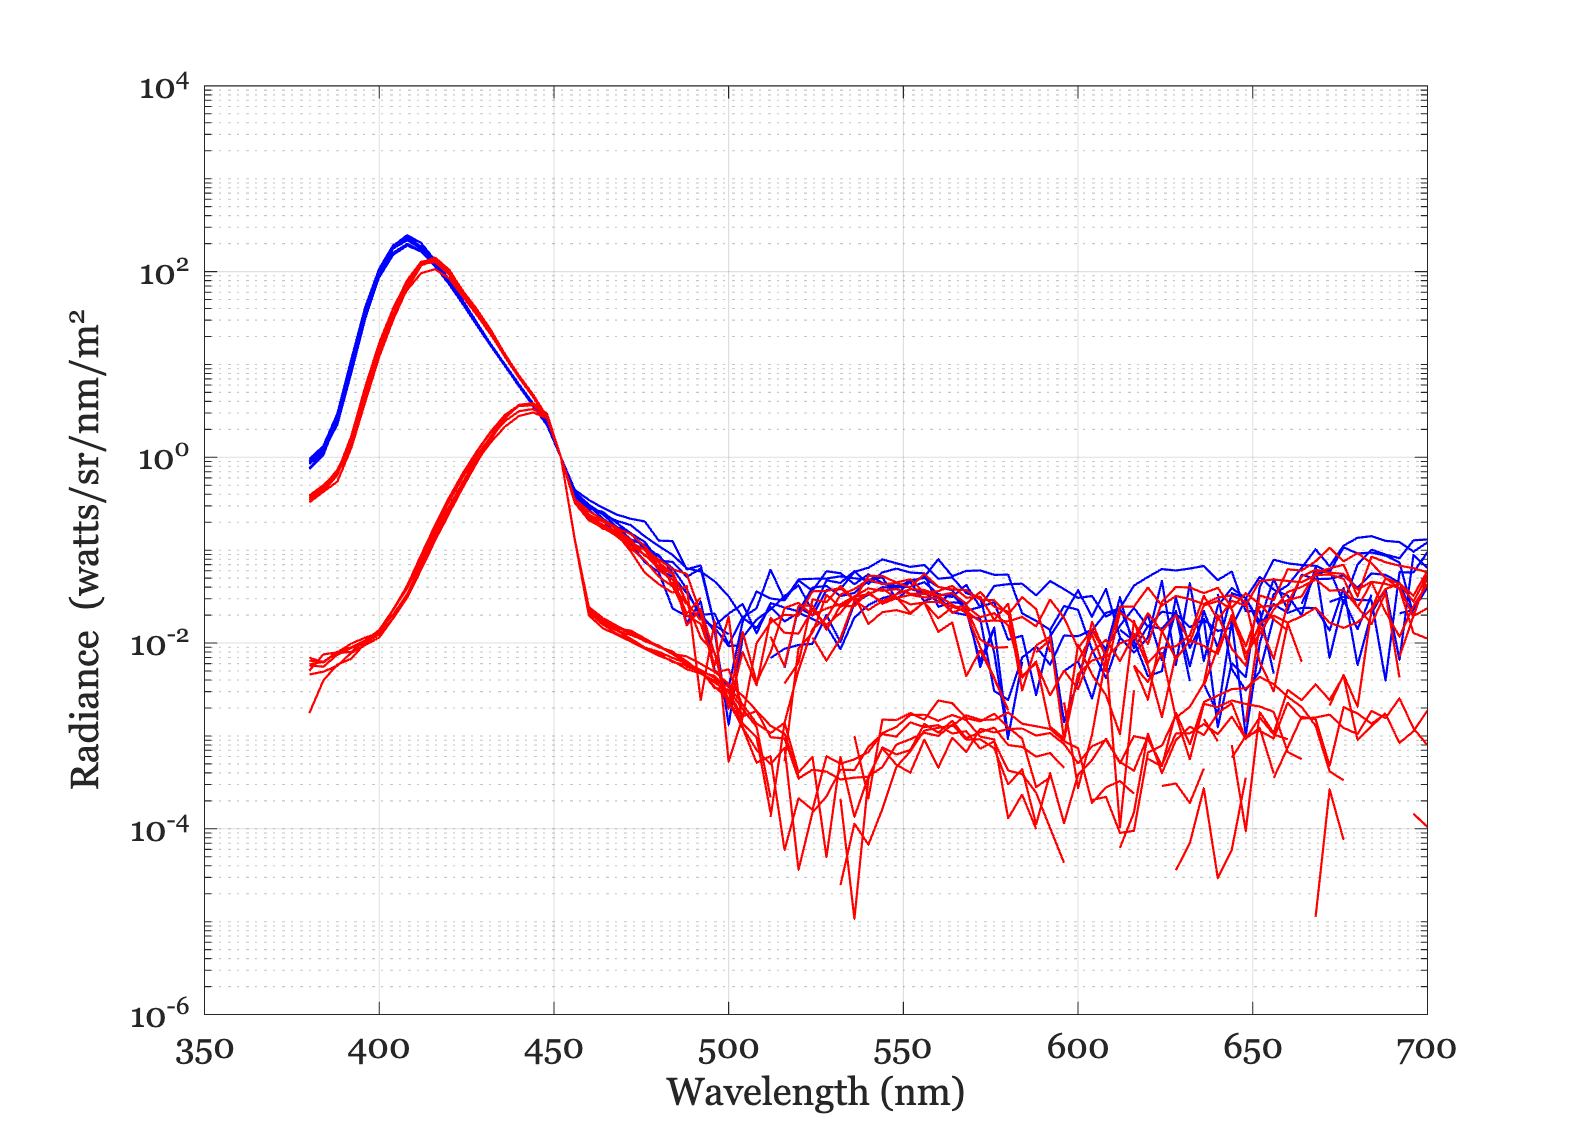

files = ieTableGet(T,'condition','calibrate','ewave',450);
data = oeReadFiles(files,'waves',waves,'normalized wave',452);
semilogy(waves,data,'r-');
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2');